# Ejercicio 3.03  

Usa la Robotics System Toolbox v2.2

Transformación homogénea en un prisma (II).

T0=eye(4);

% Dibujamos el cubo que contiene la cuña
a=4; b=8; c=2;
voxel([0 0 0],[-a b c],'r',0.1);
grid on		% Se establece una rejilla
view(115,20)	% Se establece el punto de vista
axis equal

% Representación del frame 0:
pframe(T0,'c',1.4);

% el frame 1, en color azul:
T1=trvec2tform([0 b 0]) * axang2tform([0 0 1 pi/2]) * axang2tform([1 0 0 pi/2])*T0

T1 =     0.0000   -0.0000    1.0000         0
    1.0000    0.0000   -0.0000    8.0000
         0    1.0000    0.0000         0
         0         0         0    1.0000


pframe(T1,'b',1.4);

% el frame 1, calculado en ejes moviles (postmultiplicar):
T1= T0 * axang2tform([1 0 0 pi/2]) * axang2tform([0 1 0 pi/2])*trvec2tform([b 0 0])

T1 =     0.0000         0    1.0000    0.0000
    1.0000    0.0000   -0.0000    8.0000
   -0.0000    1.0000    0.0000   -0.0000
         0         0         0    1.0000


pframe(T1,'c',.8);

% el frame 2 desde el 1, ejes móviles, en rojo:
T2= T1 * axang2tform([1 0 0 pi/2]) * axang2tform([0 0 1 pi])*trvec2tform([0 a -c])

T2 =     0.0000   -1.0000    0.0000   -4.0000
   -1.0000   -0.0000   -0.0000    8.0000
    0.0000   -0.0000   -1.0000    2.0000
         0         0         0    1.0000


pframe(T2,'r',1.4);

% el frame 2 desde el 0, debe ser igual:
T2=trvec2tform([-a b c]) * axang2tform([0 0 1 3*pi/2]) * axang2tform([1 0 0 pi])*T0

T2 =    -0.0000   -1.0000   -0.0000   -4.0000
   -1.0000    0.0000    0.0000    8.0000
         0    0.0000   -1.0000    2.0000
         0         0         0    1.0000


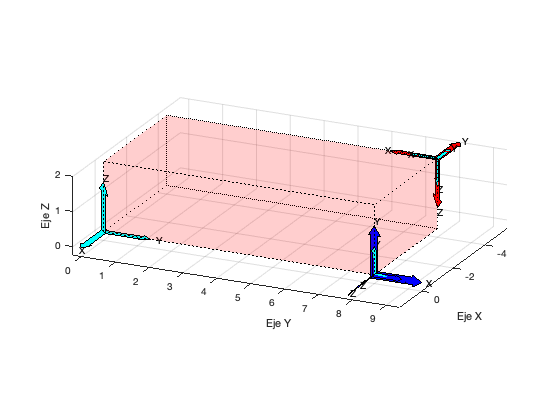

pframe(T2,'c',.8);


% el frame 2 desde el 0, ejes móviles, en amarillo:
T2= T0 * axang2tform([0 0 1 pi/2]) * axang2tform([0 1 0 pi])*trvec2tform([-b a -c])

T2 =    -0.0000   -1.0000    0.0000   -4.0000
   -1.0000    0.0000    0.0000    8.0000
   -0.0000         0   -1.0000    2.0000
         0         0         0    1.0000


% pframe(T2,'y',0.4);
